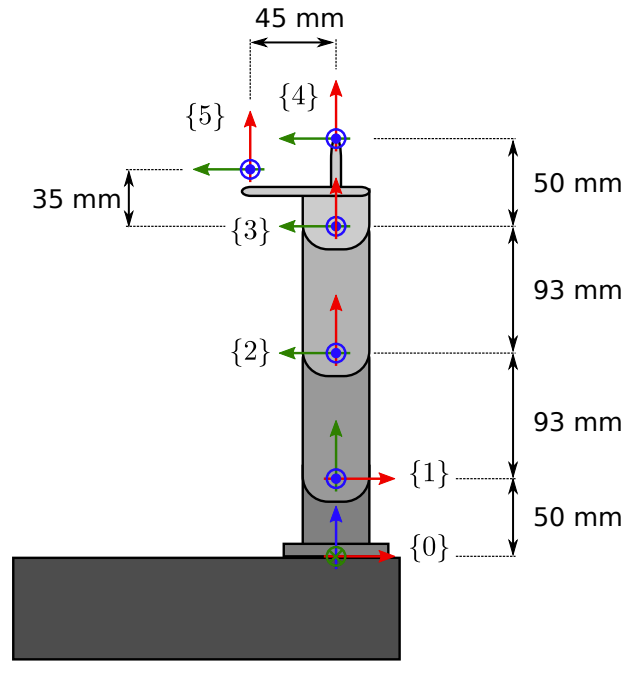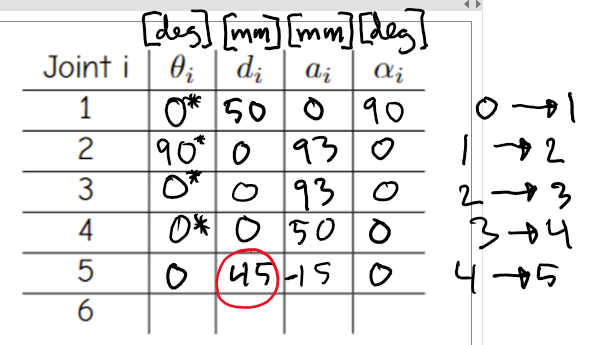

clear all
syms theta_1 theta_2 theta_3 theta_4
syms theta a d alpha
theta_1,    d_1=50e-3,  a_1=0,      alpha_1=pi/2,

$$theta\_1 = \theta_{1}$$

d_1 = 0.0500

a_1 = 0

alpha_1 = 1.5708

theta_2,    d_2=0,      a_2=93e-3,  alpha_2=0,

$$theta\_2 = \theta_{2}$$

d_2 = 0

a_2 = 0.0930

alpha_2 = 0

theta_3,    d_3=0,      a_3=93e-3,  alpha_3=0,

$$theta\_3 = \theta_{3}$$

d_3 = 0

a_3 = 0.0930

alpha_3 = 0

theta_4,    d_4=0,      a_4=50e-3,  alpha_4=0,

$$theta\_4 = \theta_{4}$$

d_4 = 0

a_4 = 0.0500

alpha_4 = 0

theta_5=0,  d_5=45e-3,   a_5=-15e-3, alpha_5=0

theta_5 = 0

d_5 = 0.0450

a_5 = -0.0150

alpha_5 = 0


A_i(theta,d,a, alpha)=([cos(theta),-sin(theta)*cos(alpha),sin(theta)*cos(alpha),a*cos(theta);
    sin(theta),cos(theta)*cos(alpha),-cos(theta)*sin(alpha),a*sin(theta); ...
    0, sin(alpha),cos(alpha),d; ...
    0,0,0,1])

$$A\_i(theta, d, a, alpha) = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \cos\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A_1=A_i(theta_1,d_1,a_1, alpha_1)

$$A\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & 0 & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_2=A_i(theta_2,d_2,a_2, alpha_2)%everything is in world frame, also inv kinematics

$$A\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right) & \frac{93\,\cos\left(\theta_{2}\right)}{1000}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3=A_i(theta_3,d_3,a_3, alpha_3)

$$A\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & \sin\left(\theta_{3}\right) & \frac{93\,\cos\left(\theta_{3}\right)}{1000}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{93\,\sin\left(\theta_{3}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_4=A_i(theta_4,d_4,a_4, alpha_4)

$$A\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & \sin\left(\theta_{4}\right) & \frac{\cos\left(\theta_{4}\right)}{20}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & \frac{\sin\left(\theta_{4}\right)}{20}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_5=A_i(theta_5,d_5,a_5, alpha_5)%Only translation

$$A\_5 = \left(\begin{array}{cccc} 1 & 0 & 0 & -\frac{3}{200}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{9}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_0_4=simplify(expand(A_1*A_2*A_3*A_4))

$$T\_0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{4}+\sigma_{3} & -\sigma_{1}-\sigma_{2} & \cos\left(\theta_{1}\right)\,\left(\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)\right) & \frac{\cos\left(\theta_{1}\right)\,\sigma_{6}}{1000}\\ \sigma_{2}-\sigma_{1} & \sigma_{4}-\sigma_{3} & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{1}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right) & \frac{\sin\left(\theta_{1}\right)\,\sigma_{6}}{1000}\\ \sigma_{5} & \sigma_{7} & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right) & \frac{\sigma_{5}}{20}+\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}+\frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{2}=\frac{\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{3}=\frac{\cos\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{4}=\frac{\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{5}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{6}=50\,\sigma_{7}+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{7}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

T_0_5=A_1*A_2*A_3*A_4*A_5

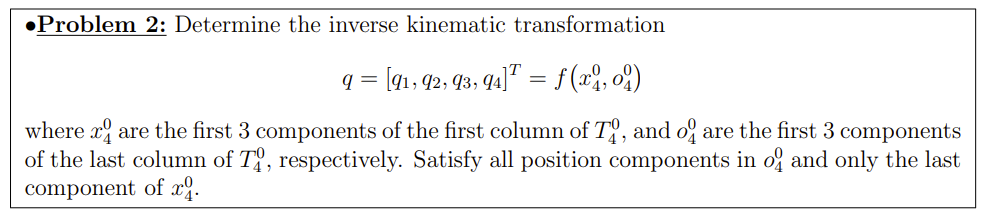


x_0_4=T_0_4(1:3,1)      %???    

$$x\_0\_4 = \left(\begin{array}{c} \frac{\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}+\frac{\cos\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \frac{\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}-\frac{\sin\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)$$

o_0_4=T_0_4(1:3,end);    %position
syms x_c y_c z_c theta_t4 %knowen input parameters
syms d_1
syms a_ theta_ [1 4]
display("-------INVERSE KIN STARTS HERE------------------------")

    "-------INVERSE KIN STARTS HERE------------------------"




%theta_1
theta_1_sol=atan2(y_c,x_c)

$$theta\_1\_sol = \text{atan2}\left(y_{c},x_{c}\right)$$


%theta_3
r=sqrt(x_c^2+y_c^2)

$$r = \sqrt{{x_{c}}^{2}+{y_{c}}^{2}}$$

theta_t4_eq=theta_t4==theta_2+theta_3+theta_4

$$theta\_t4\_eq = \theta_{\mathrm{t4}}=\theta_{2}+\theta_{3}+\theta_{4}$$

d_22=a_4*sin(theta_t4)

$$d\_22 = a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right)$$

r_22=a_4*cos(theta_t4)

$$r\_22 = a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)$$

r_11=r-r_22

$$r\_11 = \sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)$$

d_33=z_c-d_1-d_22

$$d\_33 = z_{c}-d_{1}-a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right)$$

c_2=sqrt(r_11^2+d_33^2);
C_2theta=pi-theta_3;
theta_3_sol=solve(c_2^2==a_2^2+a_3^2-2*a_2*a_3*cos(C_2theta),theta_3)

$$theta\_3\_sol = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{acos}\left(\frac{\frac{{\left(d_{1}-z_{c}+a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2}-\frac{{a_{2}}^{2}}{2}-\frac{{a_{3}}^{2}}{2}+\frac{{\left(\sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2}}{a_{2}\,a_{3}}\right) \end{array}$$

theta_3_sol=theta_3_sol(1)

$$theta\_3\_sol = \mathrm{acos}\left(\frac{\frac{{\left(d_{1}-z_{c}+a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2}-\frac{{a_{2}}^{2}}{2}-\frac{{a_{3}}^{2}}{2}+\frac{{\left(\sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2}}{a_{2}\,a_{3}}\right)$$


%theta_2

$$theta\_2\_eq = \sqrt{{x_{c}}^{2}+{y_{c}}^{2}}=a_{4}\,\theta_{\mathrm{t4}}+a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\cos\left(\theta_{2}\right)$$

theta_2_sol=atan2(d_33,r_11)-atan2(sin(theta_3_sol)*a_3,a_2+cos(theta_3_sol)*a_3)%other way

$$theta\_2\_sol = \begin{array}{l} \text{atan2}\left(z_{c}-d_{1}-a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right),\sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)\right)-\text{atan2}\left(a_{3}\,\sqrt{1-\frac{{\sigma_{1}}^{2}}{{a_{2}}^{2}\,{a_{3}}^{2}}},a_{2}+\frac{\sigma_{1}}{a_{2}}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left(d_{1}-z_{c}+a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2}-\frac{{a_{2}}^{2}}{2}-\frac{{a_{3}}^{2}}{2}+\frac{{\left(\sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2} \end{array}$$


%theta_4
%theta_t4==theta_2+theta_3+theta_4 =>
theta_4_sol=theta_t4-theta_2_sol-theta_3_sol

$$theta\_4\_sol = \begin{array}{l} \theta_{\mathrm{t4}}-\mathrm{acos}\left(\frac{\sigma_{1}}{a_{2}\,a_{3}}\right)-\text{atan2}\left(z_{c}-d_{1}-a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right),\sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)\right)+\text{atan2}\left(a_{3}\,\sqrt{1-\frac{{\sigma_{1}}^{2}}{{a_{2}}^{2}\,{a_{3}}^{2}}},a_{2}+\frac{\sigma_{1}}{a_{2}}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left(d_{1}-z_{c}+a_{4}\,\sin\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2}-\frac{{a_{2}}^{2}}{2}-\frac{{a_{3}}^{2}}{2}+\frac{{\left(\sqrt{{x_{c}}^{2}+{y_{c}}^{2}}-a_{4}\,\cos\left(\theta_{\mathrm{t4}}\right)\right)}^{2}}{2} \end{array}$$

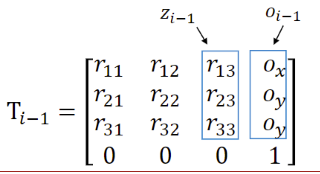

%test
syms theta_1 theta_2 theta_3 theta_4
syms theta a d alpha
theta_1,    d_1=50e-3,  a_1=0,      alpha_1=pi/2,

$$theta\_1 = \theta_{1}$$

d_1 = 0.0500

a_1 = 0

alpha_1 = 1.5708

theta_2,    d_2=0,      a_2=93e-3,  alpha_2=0,

$$theta\_2 = \theta_{2}$$

d_2 = 0

a_2 = 0.0930

alpha_2 = 0

theta_3,    d_3=0,      a_3=93e-3,  alpha_3=0,

$$theta\_3 = \theta_{3}$$

d_3 = 0

a_3 = 0.0930

alpha_3 = 0

theta_4,    d_4=0,      a_4=50e-3,  alpha_4=0,

$$theta\_4 = \theta_{4}$$

d_4 = 0

a_4 = 0.0500

alpha_4 = 0

theta_5=0,  d_5=pi/4,   a_5=-15e-3, alpha_5=0

theta_5 = 0

d_5 = 0.7854

a_5 = -0.0150

alpha_5 = 0

x_c=100e-3,y_c=100e-3,z_c=140e-3,theta_t4=pi/4 %

x_c = 0.1000

y_c = 0.1000

z_c = 0.1400

theta_t4 = 0.7854

theta_1_num=eval(theta_1_sol)

theta_1_num = 0.7854

theta_3_num=eval(theta_3_sol)

theta_3_num = 1.7487

theta_2_num=eval(theta_2_sol)

theta_2_num = -0.3986

theta_4_num=eval(theta_4_sol)

theta_4_num = -0.5647


T_0_4_num=eval(subs(T_0_4,[theta_1 theta_2 theta_3 theta_4],[theta_1_num theta_2_num theta_3_num theta_4_num]))

T_0_4_num =     0.5000   -0.5000    0.2841    0.1000
    0.5000   -0.5000   -0.4231    0.1000
    0.7071    0.7071   -0.9042    0.1400
         0         0         0    1.0000


position=T_0_4_num(1:3,4)

position =     0.1000
    0.1000
    0.1400


vinkel=asin(T_0_4_num(3,1))

vinkel = 0.7854

%inverse kinematic gives the same as forward kinematic

%med funktion
cd("C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\7. semester\robotics\projekt")
[theta_1 theta_2 theta_3 theta_4] = invKinematic(x_c,y_c,z_c,theta_t4)

theta_1 = 0.7854

theta_2 = -0.3986

theta_3 = 1.7487

theta_4 = -0.5647

%visualisring
x_c=0e-3,y_c=100e-3,z_c=200e-3,theta_t4=pi/4 %

x_c = 0

y_c = 0.1000

z_c = 0.2000

theta_t4 = 0.7854

[theta_1 theta_2 theta_3 theta_4] = invKinematic(x_c,y_c,z_c,theta_t4)

theta_1 = 1.5708

theta_2 = 1.8421

theta_3 = -1.5694

theta_4 = 0.5127

x_cor=[0,0,cos(theta_2)*a_2,cos(theta_2+theta_3)*a_3,cos(theta_2+theta_3+theta_4)*a_4]

x_cor =          0         0   -0.0249    0.0896    0.0354


y_cor=[0,d_1,sin(theta_2)*a_2,sin(theta_2+theta_3)*a_3,sin(theta_2+theta_3+theta_4)*a_4]

y_cor =          0    0.0500    0.0896    0.0250    0.0354


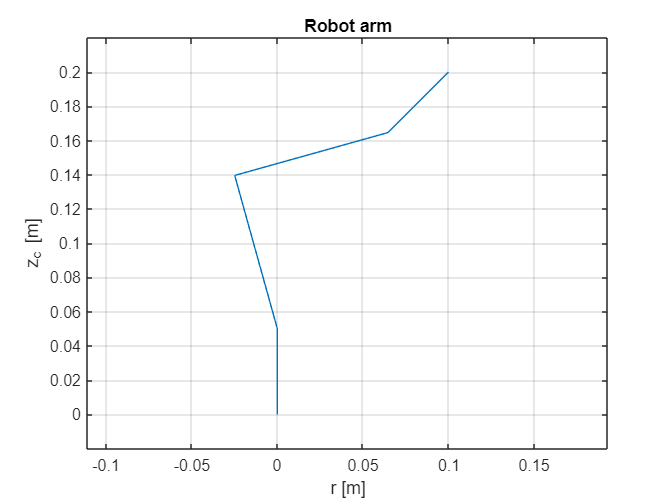

plot(cumsum(x_cor)',cumsum(y_cor)')
xlim("padded"),ylim("padded"),grid on,xlabel("r [m]"),ylabel("z_c [m]"),axis equal,title("Robot arm")

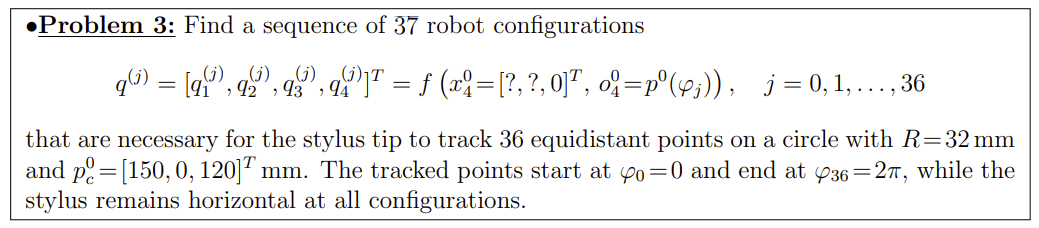

%problem 3
syms phi p__0_c
%circle definition
R = 0.032

R = 0.0320

p__0_c = [0.150;0;0.120]

p__0_c =     0.1500
         0
    0.1200


p0 = p__0_c + R*[0;cos(phi);sin(phi)]

$$p0 = \left(\begin{array}{c} \frac{3}{20}\\ \frac{4\,\cos\left(\varphi \right)}{125}\\ \frac{4\,\sin\left(\varphi \right)}{125}+\frac{3}{25} \end{array}\right)$$

circle=[];theta=zeros(4,0);
%invkin function
%cd("C:\Users\Skipper\Desktop\Robotics")
%position loop
n = 0

n = 0

while n < 37
    phiC = (2*pi/32)*n
    circle =[circle, eval(subs(p0,phi,phiC))];
    [theta_1 theta_2 theta_3 theta_4] = invKinematic(circle(1,n+1),circle(2,n+1),circle(3,n+1),(90*(pi/180)));
    theta=[theta,[theta_1 theta_2 theta_3 theta_4]'];
    n = n + 1
end

phiC = 0

n = 1

phiC = 0.1963

n = 2

phiC = 0.3927

n = 3

phiC = 0.5890

n = 4

phiC = 0.7854

n = 5

phiC = 0.9817

n = 6

phiC = 1.1781

n = 7

phiC = 1.3744

n = 8

phiC = 1.5708

n = 9

phiC = 1.7671

n = 10

phiC = 1.9635

n = 11

phiC = 2.1598

n = 12

phiC = 2.3562

n = 13

phiC = 2.5525

n = 14

phiC = 2.7489

n = 15

phiC = 2.9452

n = 16

phiC = 3.1416

n = 17

phiC = 3.3379

n = 18

phiC = 3.5343

n = 19

phiC = 3.7306

n = 20

phiC = 3.9270

n = 21

phiC = 4.1233

n = 22

phiC = 4.3197

n = 23

phiC = 4.5160

n = 24

phiC = 4.7124

n = 25

phiC = 4.9087

n = 26

phiC = 5.1051

n = 27

phiC = 5.3014

n = 28

phiC = 5.4978

n = 29

phiC = 5.6941

n = 30

phiC = 5.8905

n = 31

phiC = 6.0868

n = 32

phiC = 6.2832

n = 33

phiC = 6.4795

n = 34

phiC = 6.6759

n = 35

phiC = 6.8722

n = 36

phiC = 7.0686

n = 37

circle,theta

circle =     0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500
    0.0320    0.0314    0.0296    0.0266    0.0226    0.0178    0.0122    0.0062         0   -0.0062   -0.0122   -0.0178   -0.0226   -0.0266   -0.0296   -0.0314   -0.0320   -0.0314   -0.0296   -0.0266   -0.0226   -0.0178   -0.0122   -0.0062         0    0.0062    0.0122    0.0178    0.0226    0.0266    0.0296    0.0314    0.0320    0.0314    0.0296    0.0266    0.0226
    0.1200    0.1262    0.1322    0.1378    0.1426    0.1466    0.1496    0.1514    0.1520    0.1514    0.1496    0.1466    0.1426    0.1378    0.1322    0.1262    0.1200    0.1138    0.1078    0.1022    0.0974    0.0934    0.0904    0.0886    0.088

theta =     0.2102    0.2063    0.1946    0.1756    0.1497    0.1180    0.0815    0.0416         0   -0.0416   -0.0815   -0.1180   -0.1497   -0.1756   -0.1946   -0.2063   -0.2102   -0.2063   -0.1946   -0.1756   -0.1497   -0.1180   -0.0815   -0.0416         0    0.0416    0.0815    0.1180    0.1497    0.1756    0.1946    0.2063    0.2102    0.2063    0.1946    0.1756    0.1497
   -0.4592    0.7506   -0.3656    0.8095   -0.2862   -0.2558   -0.2331   -0.2191    0.8818   -0.2191   -0.2331   -0.2558   -0.2862    0.8095   -0.3656    0.7506   -0.4592   -0.5071    0.6548   -0.5963    0.5995    0.5780   -0.6888    0.5519   -0.7081    0.5519   -0.6888    0.5780    0.5995   -0.5963    0.6548   -0.5071   -0.4592    0.7506   -0.3656    0.8095   -0.2862
    1.1777   -1.1620    1.1468   -1.1328    1.1203    1.1101    1.1024    1.0977   -1.0961    1.0977    1.1024    1.1101    1.1203   -1.1328    1.1468   -1.1620    1.1777    1.1933   -1.2082    1.2218   -1.2337   -1.2435    1.2507   -1.2551    1.2566

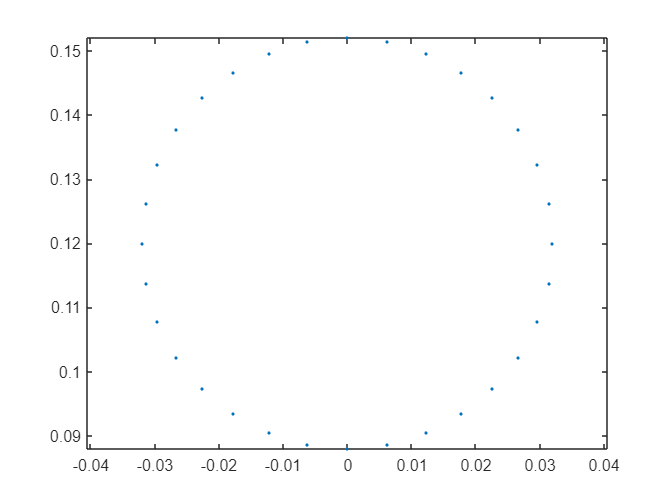

plot(circle(2,:),circle(3,:),"."),axis equal

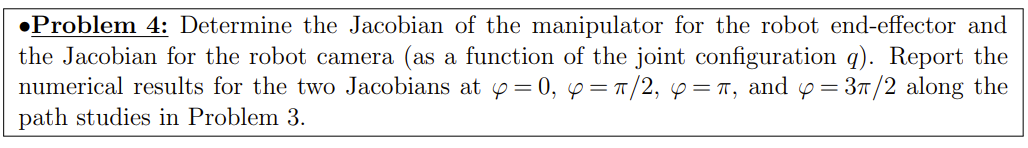

%Q4
syms t1 t2 t3 t4
t0=0

t0 = 0

T_0=A_i(t0, 0, 0, 0)

$$T\_0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1=A_i(t1, 50, 0, pi/2)

$$T\_1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & 0 & 0 & 0\\ \sin\left(t_{1}\right) & 0 & -\cos\left(t_{1}\right) & 0\\ 0 & 1 & 0 & 50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2=A_i(t2,0,93,0)

$$T\_2 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & \sin\left(t_{2}\right) & 93\,\cos\left(t_{2}\right)\\ \sin\left(t_{2}\right) & \cos\left(t_{2}\right) & 0 & 93\,\sin\left(t_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3=A_i(t3,0,93,0)

$$T\_3 = \left(\begin{array}{cccc} \cos\left(t_{3}\right) & -\sin\left(t_{3}\right) & \sin\left(t_{3}\right) & 93\,\cos\left(t_{3}\right)\\ \sin\left(t_{3}\right) & \cos\left(t_{3}\right) & 0 & 93\,\sin\left(t_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_4=A_i(t4,0,50,0)

$$T\_4 = \left(\begin{array}{cccc} \cos\left(t_{4}\right) & -\sin\left(t_{4}\right) & \sin\left(t_{4}\right) & 50\,\cos\left(t_{4}\right)\\ \sin\left(t_{4}\right) & \cos\left(t_{4}\right) & 0 & 50\,\sin\left(t_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_5=A_i(0,45,-15,0)

$$T\_5 = \left(\begin{array}{cccc} 1 & 0 & 0 & -15\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 45\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Now that we have our transformation-matrices, we can get the manipulator Jacobian

J_1=eval([cross(T_0(1:3,3),(T_5(1:3,4)-T_0(1:3,4)));T_0(1:3,3)])

J_1 =      0
   -15
     0
     0
     0
     1


J_2=eval([cross(T_1(1:3,3),(T_5(1:3,4)-T_1(1:3,4)));T_1(1:3,3)])

$$J\_2 = \left(\begin{array}{c} 5\,\cos\left(t_{1}\right)\\ 0\\ -15\,\cos\left(t_{1}\right)\\ 0\\ -\cos\left(t_{1}\right)\\ 0 \end{array}\right)$$

J_3=eval([cross(T_2(1:3,3),(T_5(1:3,4)-T_2(1:3,4)));T_2(1:3,3)])

$$J\_3 = \left(\begin{array}{c} 93\,\sin\left(t_{2}\right)\\ -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15\\ -93\,{\sin\left(t_{2}\right)}^{2}\\ \sin\left(t_{2}\right)\\ 0\\ 1 \end{array}\right)$$

J_4=eval([cross(T_4(1:3,3),(T_5(1:3,4)-T_4(1:3,4)));T_4(1:3,3)])

$$J\_4 = \left(\begin{array}{c} 50\,\sin\left(t_{4}\right)\\ -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15\\ -50\,{\sin\left(t_{4}\right)}^{2}\\ \sin\left(t_{4}\right)\\ 0\\ 1 \end{array}\right)$$

J_5=eval([cross(T_5(1:3,3),(T_5(1:3,4)-T_1(1:3,4)));T_5(1:3,3)])

J_5 =      0
   -15
     0
     0
     0
     1


J_end=[J_1, J_2, J_3, J_4]

$$J\_end = \left(\begin{array}{cccc} 0 & 5\,\cos\left(t_{1}\right) & 93\,\sin\left(t_{2}\right) & 50\,\sin\left(t_{4}\right)\\ -15 & 0 & -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15 & -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15\\ 0 & -15\,\cos\left(t_{1}\right) & -93\,{\sin\left(t_{2}\right)}^{2} & -50\,{\sin\left(t_{4}\right)}^{2}\\ 0 & 0 & \sin\left(t_{2}\right) & \sin\left(t_{4}\right)\\ 0 & -\cos\left(t_{1}\right) & 0 & 0\\ 1 & 0 & 1 & 1 \end{array}\right)$$

J_cam=[J_1, J_2, J_3, J_4, J_5]

$$J\_cam = \left(\begin{array}{ccccc} 0 & 5\,\cos\left(t_{1}\right) & 93\,\sin\left(t_{2}\right) & 50\,\sin\left(t_{4}\right) & 0\\ -15 & 0 & -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15 & -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15 & -15\\ 0 & -15\,\cos\left(t_{1}\right) & -93\,{\sin\left(t_{2}\right)}^{2} & -50\,{\sin\left(t_{4}\right)}^{2} & 0\\ 0 & 0 & \sin\left(t_{2}\right) & \sin\left(t_{4}\right) & 0\\ 0 & -\cos\left(t_{1}\right) & 0 & 0 & 0\\ 1 & 0 & 1 & 1 & 1 \end{array}\right)$$

Xi_end(t1,t2,t3,t4)=J_end

$$Xi\_end(t1, t2, t3, t4) = \left(\begin{array}{cccc} 0 & 5\,\cos\left(t_{1}\right) & 93\,\sin\left(t_{2}\right) & 50\,\sin\left(t_{4}\right)\\ -15 & 0 & -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15 & -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15\\ 0 & -15\,\cos\left(t_{1}\right) & -93\,{\sin\left(t_{2}\right)}^{2} & -50\,{\sin\left(t_{4}\right)}^{2}\\ 0 & 0 & \sin\left(t_{2}\right) & \sin\left(t_{4}\right)\\ 0 & -\cos\left(t_{1}\right) & 0 & 0\\ 1 & 0 & 1 & 1 \end{array}\right)$$

Xi_cam(t1,t2,t3,t4)=J_cam

$$Xi\_cam(t1, t2, t3, t4) = \left(\begin{array}{ccccc} 0 & 5\,\cos\left(t_{1}\right) & 93\,\sin\left(t_{2}\right) & 50\,\sin\left(t_{4}\right) & 0\\ -15 & 0 & -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15 & -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15 & -15\\ 0 & -15\,\cos\left(t_{1}\right) & -93\,{\sin\left(t_{2}\right)}^{2} & -50\,{\sin\left(t_{4}\right)}^{2} & 0\\ 0 & 0 & \sin\left(t_{2}\right) & \sin\left(t_{4}\right) & 0\\ 0 & -\cos\left(t_{1}\right) & 0 & 0 & 0\\ 1 & 0 & 1 & 1 & 1 \end{array}\right)$$

Xi_end(0,0,0,0)

$$ans = \left(\begin{array}{cccc} 0 & 5 & 0 & 0\\ -15 & 0 & -108 & -65\\ 0 & -15 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & -1 & 0 & 0\\ 1 & 0 & 1 & 1 \end{array}\right)$$

Xi_cam(0,0,0,0)

$$ans = \left(\begin{array}{ccccc} 0 & 5 & 0 & 0 & 0\\ -15 & 0 & -108 & -65 & -15\\ 0 & -15 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 & 0\\ 1 & 0 & 1 & 1 & 1 \end{array}\right)$$

J_end(t1,t2,t3,t4)=J_end

$$J\_end(t1, t2, t3, t4) = \left(\begin{array}{cccc} 0 & 5\,\cos\left(t_{1}\right) & 93\,\sin\left(t_{2}\right) & 50\,\sin\left(t_{4}\right)\\ -15 & 0 & -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15 & -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15\\ 0 & -15\,\cos\left(t_{1}\right) & -93\,{\sin\left(t_{2}\right)}^{2} & -50\,{\sin\left(t_{4}\right)}^{2}\\ 0 & 0 & \sin\left(t_{2}\right) & \sin\left(t_{4}\right)\\ 0 & -\cos\left(t_{1}\right) & 0 & 0\\ 1 & 0 & 1 & 1 \end{array}\right)$$

J_cam(t1,t2,t3,t4)=J_cam

$$J\_cam(t1, t2, t3, t4) = \left(\begin{array}{ccccc} 0 & 5\,\cos\left(t_{1}\right) & 93\,\sin\left(t_{2}\right) & 50\,\sin\left(t_{4}\right) & 0\\ -15 & 0 & -93\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)-15 & -50\,\cos\left(t_{4}\right)-45\,\sin\left(t_{4}\right)-15 & -15\\ 0 & -15\,\cos\left(t_{1}\right) & -93\,{\sin\left(t_{2}\right)}^{2} & -50\,{\sin\left(t_{4}\right)}^{2} & 0\\ 0 & 0 & \sin\left(t_{2}\right) & \sin\left(t_{4}\right) & 0\\ 0 & -\cos\left(t_{1}\right) & 0 & 0 & 0\\ 1 & 0 & 1 & 1 & 1 \end{array}\right)$$

%problem 4 verification
%circle definition
R = 0.032

R = 0.0320

p__0_c = [0.150;0;0.120]

p__0_c =     0.1500
         0
    0.1200


p0 = p__0_c + R*[0;cos(phi);sin(phi)]

$$p0 = \left(\begin{array}{c} \frac{3}{20}\\ \frac{4\,\cos\left(\varphi \right)}{125}\\ \frac{4\,\sin\left(\varphi \right)}{125}+\frac{3}{25} \end{array}\right)$$


%position loop
n = 0

n = 0


phi1 = 0

phi1 = 0

circle1 = eval(subs(p0,phi,phi1))

circle1 =     0.1500
    0.0320
    0.1200


[theta_1 theta_2 theta_3 theta_4] = invKinematic(circle1(1,1),circle1(2,1),circle1(3,1),(90*(pi/180)))

theta_1 = 0.2102

theta_2 = -0.4592

theta_3 = 1.1777

theta_4 = 0.8523

eval(J_end(theta_1, theta_2, theta_3, theta_4))

ans =          0    4.8900  -41.2191   37.6391
  -15.0000         0  -78.4219  -81.7887
         0  -14.6699  -18.2689  -28.3341
         0         0   -0.4432    0.7528
         0   -0.9780         0         0
    1.0000         0    1.0000    1.0000


eval(J_cam(theta_1, theta_2, theta_3, theta_4))

ans =          0    4.8900  -41.2191   37.6391         0
  -15.0000         0  -78.4219  -81.7887  -15.0000
         0  -14.6699  -18.2689  -28.3341         0
         0         0   -0.4432    0.7528         0
         0   -0.9780         0         0         0
    1.0000         0    1.0000    1.0000    1.0000



phi2 = pi/2

phi2 = 1.5708

circle2 = eval(subs(p0,phi,phi2))

circle2 =     0.1500
         0
    0.1520


[theta_1 theta_2 theta_3 theta_4] = invKinematic(circle2(1,1),circle2(2,1),circle2(3,1),(90*(pi/180)))

theta_1 = 0

theta_2 = 0.8818

theta_3 = -1.0961

theta_4 = 1.7852

eval(J_end(theta_1, theta_2, theta_3, theta_4))

ans =          0    5.0000   71.7831   48.8556
  -15.0000         0 -108.8623  -48.3340
         0  -15.0000  -55.4067  -47.7375
         0         0    0.7719    0.9771
         0   -1.0000         0         0
    1.0000         0    1.0000    1.0000


eval(J_cam(theta_1, theta_2, theta_3, theta_4))

ans =          0    5.0000   71.7831   48.8556         0
  -15.0000         0 -108.8623  -48.3340  -15.0000
         0  -15.0000  -55.4067  -47.7375         0
         0         0    0.7719    0.9771         0
         0   -1.0000         0         0         0
    1.0000         0    1.0000    1.0000    1.0000



phi3 = pi

phi3 = 3.1416

circle3 = eval(subs(p0,phi,phi3))

circle3 =     0.1500
   -0.0320
    0.1200


[theta_1 theta_2 theta_3 theta_4] = invKinematic(circle3(1,1),circle3(2,1),circle3(3,1),(90*(pi/180)))

theta_1 = -0.2102

theta_2 = -0.4592

theta_3 = 1.1777

theta_4 = 0.8523

eval(J_end(theta_1, theta_2, theta_3, theta_4))

ans =          0    4.8900  -41.2191   37.6391
  -15.0000         0  -78.4219  -81.7887
         0  -14.6699  -18.2689  -28.3341
         0         0   -0.4432    0.7528
         0   -0.9780         0         0
    1.0000         0    1.0000    1.0000


eval(J_cam(theta_1, theta_2, theta_3, theta_4))

ans =          0    4.8900  -41.2191   37.6391         0
  -15.0000         0  -78.4219  -81.7887  -15.0000
         0  -14.6699  -18.2689  -28.3341         0
         0         0   -0.4432    0.7528         0
         0   -0.9780         0         0         0
    1.0000         0    1.0000    1.0000    1.0000



phi4 = 3*pi/2

phi4 = 4.7124

circle4 = eval(subs(p0,phi,phi4))

circle4 =     0.1500
         0
    0.0880


[theta_1 theta_2 theta_3 theta_4] = invKinematic(circle4(1,1),circle4(2,1),circle4(3,1),(90*(pi/180)))

theta_1 = 0

theta_2 = -0.7081

theta_3 = 1.2566

theta_4 = 1.0223

eval(J_end(theta_1, theta_2, theta_3, theta_4))

ans =          0    5.0000  -60.4885   42.6662
  -15.0000         0  -56.3723  -79.4687
         0  -15.0000  -39.3426  -36.4080
         0         0   -0.6504    0.8533
         0   -1.0000         0         0
    1.0000         0    1.0000    1.0000


eval(J_cam(theta_1, theta_2, theta_3, theta_4))

ans =          0    5.0000  -60.4885   42.6662         0
  -15.0000         0  -56.3723  -79.4687  -15.0000
         0  -15.0000  -39.3426  -36.4080         0
         0         0   -0.6504    0.8533         0
         0   -1.0000         0         0         0
    1.0000         0    1.0000    1.0000    1.0000


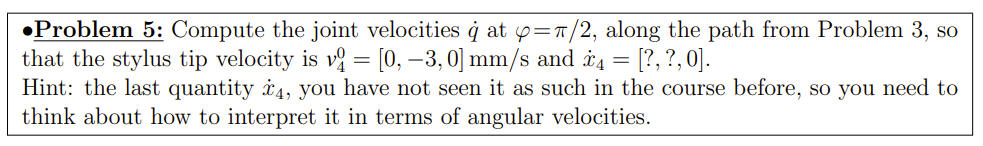


syms q_dot [4 1] %joint velocities
q_dot

$$q\_dot = \left(\begin{array}{c} q_{\mathrm{dot1}}\\ q_{\mathrm{dot2}}\\ q_{\mathrm{dot3}}\\ q_{\mathrm{dot4}} \end{array}\right)$$

v_4__0=[0,-3,0]';
circle_pos=eval(subs(p0,phi,pi/2))%phi=pi/2

circle_pos =     0.1500
         0
    0.1520


[theta_1 theta_2 theta_3 theta_4] =invKinematic(circle_pos(1),circle_pos(2),circle_pos(3),pi/2)

theta_1 = 0

theta_2 = 0.8818

theta_3 = -1.0961

theta_4 = 1.7852

J_end_pos=eval(J_end(theta_1,theta_2,theta_3,theta_4))

J_end_pos =          0    5.0000   71.7831   48.8556
  -15.0000         0 -108.8623  -48.3340
         0  -15.0000  -55.4067  -47.7375
         0         0    0.7719    0.9771
         0   -1.0000         0         0
    1.0000         0    1.0000    1.0000


j_v_pos=J_end_pos(1:3,:)

j_v_pos =          0    5.0000   71.7831   48.8556
  -15.0000         0 -108.8623  -48.3340
         0  -15.0000  -55.4067  -47.7375


j_w_pos=J_end_pos(4:6,:)

j_w_pos =          0         0    0.7719    0.9771
         0   -1.0000         0         0
    1.0000         0    1.0000    1.0000


eq_v=v_4__0==j_v_pos*q_dot

$$eq\_v = \left(\begin{array}{c} 0=5\,q_{\mathrm{dot2}}+\frac{2525644688075737\,q_{\mathrm{dot3}}}{35184372088832}+\frac{6875819909895303\,q_{\mathrm{dot4}}}{140737488355328}\\ -3=-15\,q_{\mathrm{dot1}}-\frac{3830251275947449\,q_{\mathrm{dot3}}}{35184372088832}-\frac{6802402740028223\,q_{\mathrm{dot4}}}{140737488355328}\\ 0=-15\,q_{\mathrm{dot2}}-\frac{3898896878335375\,q_{\mathrm{dot3}}}{70368744177664}-\frac{6718451492320221\,q_{\mathrm{dot4}}}{140737488355328} \end{array}\right)$$

[q_dot(1),q_dot(2),q_dot(3),q_dot(4)]=solve(eq_v,q_dot);
q_dot=eval(q_dot)%giver det mening???

q_dot =     0.2000
         0
         0
         0


w_n=j_w_pos*q_dot;

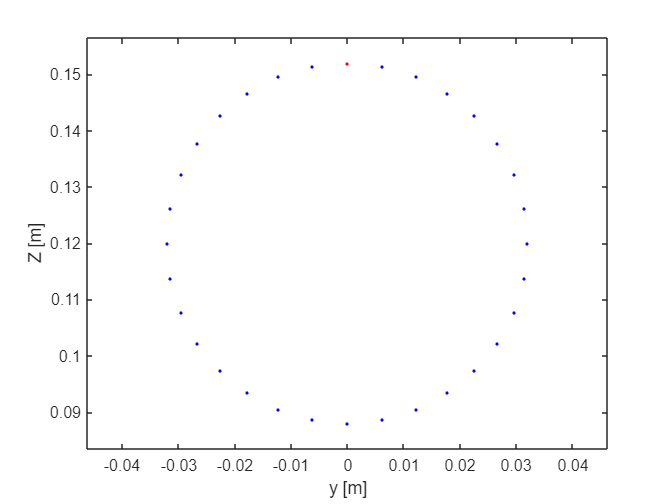

clf
plot(circle(2,:),circle(3,:),".","Color","b"),axis equal,ylabel("Z [m]"),xlabel("y [m]"), axis padded
hold on
plot(circle_pos(2,:),circle_pos(3,:),".","Color","r"),axis equal,ylabel("Z [m]"),xlabel("y [m]"), axis padded
hold off